load lhd1sam0.545.mat

CAN 통신

scout = canChannel('PEAK-System', 'PCAN_USBBUS1')

scout =   Channel - 속성 있음:

   Device Information
            DeviceVendor: 'PEAK-System'
                  Device: 'PCAN_USBBUS1'
      DeviceChannelIndex: 1
      DeviceSerialNumber: '0'
            ProtocolMode: 'CAN'

   Status Information
                 Running: 0
       MessagesAvailable: 0
        MessagesReceived: 0
     MessagesTransmitted: 0
    InitializationAccess: 1
        InitialTimestamp: [0×0 datetime]
           FilterHistory: 'Standard ID Filter: Allow All | Extended ID Filter: Allow All'

   Channel Information
              SilentMode: 0
                BusSpeed: 500000
                     SJW: []
                   TSEG1: []
                   TSEG2: []
            NumOfSamples: []

   Other Information
                Database: []
                UserData: []



start(scout)

message = receive(scout, Inf, "OutputFormat", "timetable")

message = 838×8 timetable
       Time        ID     Extended       Name                  Data                Length      Signals       Error    Remote
    ___________    ___    ________    __________    ___________________________    ______    ____________    _____    ______

    -0.018383초    545     false      {0×0 char}    {[        0 0 0 0 0 0 0 0]}      8       {0×0 struct}    false    false 
    -0.018121초    785     false      {0×0 char}    {[255 255 255 255 0 0 0 1]}      8       {0×0 struct}    false    false 
    -0.012976초    593     false      {0×0 char}    {[        0 0 0 0 0 0 0 0]}      8       {0×0 struct}    false    false 
    -0.010976초    594     false      {0×0 char}    {[        0 0 0 1 0 0 0 0]}      8       {0×0 struct}    false    false 
    -0.00897초     595     false      {0×0 char}    {[        0 0 0 0 0 0 0 0]}      8       {0×0 struct}    false    false 
    -0.006966초    596     false      {0×0 char}    {[        0 0 0 2 0 0 0 0]}      8       {0×0 struct

Table 3.5 Control Mode Setting Frame

TxMsg = canMessage(1057, false, 1);
TxMsg.Data = [1];
transmit(scout,TxMsg)

path = [0 7 7 -7 -7 -0.5; 0 0 12 12 0 0]'

path =          0         0
    7.0000         0
    7.0000   12.0000
   -7.0000   12.0000
   -7.0000         0
   -0.5000         0


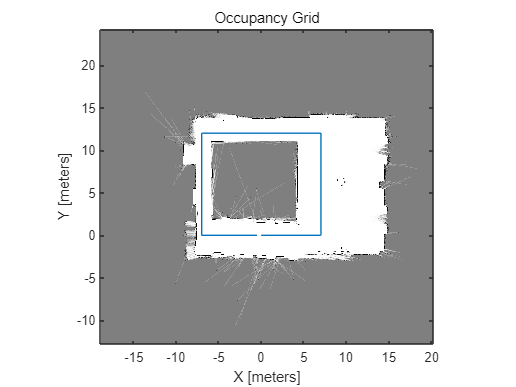


show(Map)
hold on
plot(path(:,1), path(:,2))
hold off

% Define Waypoints
% path = poses(:,1:2);
% path = pose;
robotInitialLocation = path(1,:);
robotGoal = path(end,:);

initialOrientation = 0;

robotCurrentPose = [robotInitialLocation initialOrientation]';

% Create a Kinematic Robot Model
% robot = differentialDriveKinematics("TrackWidth", 0.4, ...
%     "VehicleInputs", "VehicleSpeedHeadingRate", "WheelRadius", 0.085);
robot = differentialDriveKinematics("TrackWidth", 0.4, ...
    "VehicleInputs", "VehicleSpeedHeadingRate", "WheelRadius", 0.085);
%%%%%%%% VehicleInputs 실험 필요

% figure; plot(path(:,1), path(:,2),'k--d')

% Define the Path Following Controller
controller = controllerPurePursuit;
controller.Waypoints = path;
controller.DesiredLinearVelocity = 0.3;
controller.MaxAngularVelocity = 0.3;
controller.LookaheadDistance = 1;

% Using the Path Following Controller, Drive the Robot over the Desired Waypoints
goalRadius = 0.1;
distanceToGoal = norm(robotInitialLocation - robotGoal);

% Initialize the simulation loop
sampleTime = 0.545; % 0.545;
vizRate = rateControl(1/sampleTime);

% frameSize = robot.TrackWidth/0.2;
TxMsgs = canMessage(273, false, 8);

while( distanceToGoal > goalRadius)
    
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    
    % Get the robot's velocity using controller inputs
    vel = derivative(robot, robotCurrentPose, [v omega]);
    
    % Update the current pose
    robotCurrentPose = robotCurrentPose + vel*sampleTime; 
    
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
    
    vv = typecast(swapbytes(int16(v*1000)), "uint8");
    ome = typecast(swapbytes(int16(omega*1000)), "uint8");

    TxMsgs.Data = ([vv ome 0 0 0 0]);
    transmit(scout,TxMsgs)
    waitfor(vizRate);
end